Fs = 200; T = 1/Fs;
fp = 25;  fs = 50;  
% ========确定模拟滤波器指标======
wpz = 2*pi*fp /Fs   % ωpz

wpz =    0.250000000000000


wsz = 2*fs/Fs   % ωsz

wsz =    0.500000000000000



% ======频率变换======
wp = 2/T*tan(wpz* pi/2); rp = 3

rp =      3


ws = 2/T*tan(wsz* pi/2); rs =40

rs =     40




% ======获得巴特沃兹低通滤波器阶数和3dB截止频率======

[N, wc] = buttord(wp, ws, rp, rs, 's')

N =      6


wc =      1.856651006246013e+02


[B, A] = butter(N, wc, 's')   % 获得系统函数

B = 	1.0e+13 *

                   0                   0                   0                   0                   0                   0   4.096204815361272


A = 	1.0e+13 *

   0.000000000000100   0.000000000071735   0.000000025729900   0.000005850783186   0.000886949008123   0.085242299336095   4.096204815361272


[Bz, Az] = bilinear(B, A ,Fs)  % 使用双线性变换法获得H(z)

Bz =    0.001737585527782   0.010425513166694   0.026063782916725   0.034751710555637   0.026063782916729   0.010425513166692   0.001737585527782


Az =    1.000000000000000  -2.659046466914583   3.446507115469452  -2.563396532484714   1.138899255022832  -0.281949931978518   0.030192034663570


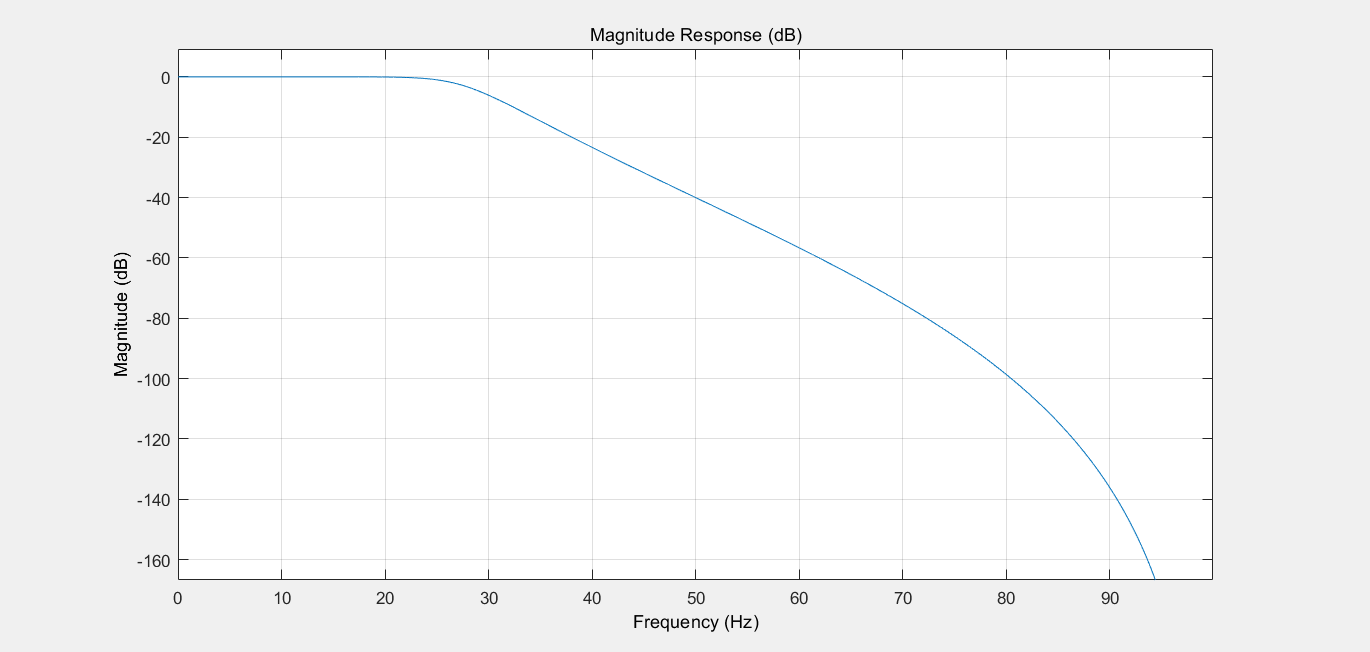


fvtool(Bz,Az,'Fs',Fs); % 显示滤波器图像

Bz, Az = biliear(B, A, Fs) ,用来 将H(s) 使用双线性变换法变成 H(z)

- Bz: 分子 

- Az:分母

事实上, matlab默认就使用T = 1的双线性变换法

[Nd, wdc] = buttord(wpz, wsz, rp, rs);
[Bdz, Adz] =butter(N, wdc);

画个图

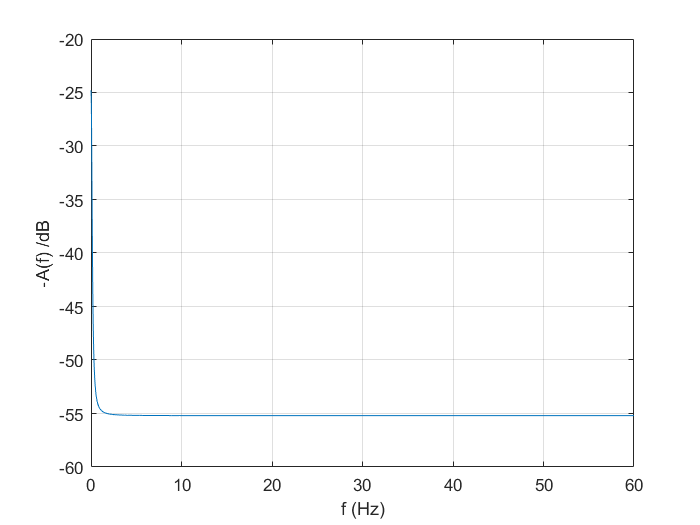


fk = 0:0.02:60;
wk = 2*pi*fk;

Hk = freqs(Bdz, Adz, wk);
plot(fk, 20 * log10(abs(Hk))); grid on;
xlabel("f (Hz)");
ylabel("-A(f) /dB")